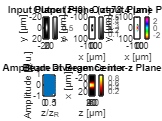

%% Parameters
lambda = 4e-6;          % Wavelength [m] (4 μm)
wo = 10e-6;             % Initial beam waist [m] (10 μm)
zR = (pi * wo^2) / lambda; % Rayleigh range [m]
dz = lambda / 20;       % Step size in z [m]
z = 0:dz:zR;            % Propagation distances [m]

N = 64;                 % Number of grid points
dx = 1e-6;              % Grid resolution [m] (1 μm)
x = (-N/2:N/2-1) * dx;  % x-axis [m]
y = x;                  % y-axis [m]
[X, Y] = meshgrid(x, y); % 2D grid

%% Analytical Gaussian Beam Propagation
k = 2 * pi / lambda;    % Wavenumber
E = zeros(N, N, length(z)); % Initialize field

for iz = 1:length(z)
    z_current = z(iz);
    w_z = wo * sqrt(1 + (z_current/zR)^2); % Beam width
    
    % Fix radius of curvature for z=0 (avoid division by zero)
    if z_current == 0
        R_z = Inf;      % Infinite curvature at waist
    else
        R_z = z_current * (1 + (zR/z_current)^2); 
    end
    
    gouy_phase = atan(z_current/zR); % Gouy phase
    
    % Electric field at z
    E(:, :, iz) = (wo / w_z) .* ...
                  exp(-(X.^2 + Y.^2)/w_z^2) .* ...
                  exp(1i*(k*z_current - gouy_phase + k*(X.^2 + Y.^2)/(2*R_z)));
end

%% Plotting (5 Plots)
figure;

% ----------------------------------------
% Plot 1: Input Plane Amplitude (z=0) - FIXED
% ----------------------------------------
subplot(2, 3, 1);
input_intensity = abs(E(:, :, 1)).^2;
imagesc(x*1e6, y*1e6, input_intensity);
title('Input Plane (z=0)');
xlabel('x [μm]'); ylabel('y [μm]');
xlim([-20 20]); ylim([-20 20]);
colormap(gca, 'gray'); 
clim([0 1]); % Fix color scaling for visibility
colorbar;

% ----------------------------------------
% Plot 2: Output Plane Amplitude (z=zR)
% ----------------------------------------
subplot(2, 3, 2);
output_intensity = abs(E(:, :, end)).^2;
imagesc(x*1e6, y*1e6, output_intensity);
title(['Output Plane (z=', num2str(z(end)*1e6), ' μm)']);
xlabel('x [μm]'); ylabel('y [μm]');
xlim([-100 100]); ylim([-100 100]);
colormap(gca, 'gray'); 
colorbar;

% ----------------------------------------
% Plot 3: Output Plane Phase (z=zR)
% ----------------------------------------
subplot(2, 3, 3);
phase = angle(E(:, :, end));
phase = mod(phase + pi, 2*pi) - pi; % Wrap phase to [-π, π]
imagesc(x*1e6, y*1e6, phase);
title('Output Plane Phase');
xlabel('x [μm]'); ylabel('y [μm]');
xlim([-100 100]); ylim([-100 100]);
colormap(gca, 'hsv'); 
colorbar;

% ----------------------------------------
% Plot 4: Wave Amplitude along z-axis (Oscillatory)
% ----------------------------------------
subplot(2, 3, 4);
center_idx = N/2 + 1; % Index for x=0, y=0
amplitude_along_z = real(squeeze(E(center_idx, center_idx, :)));
plot(z/zR, amplitude_along_z, 'LineWidth', 2);
title('Wave Amplitude at Beam Center');
xlabel('z/z_R'); ylabel('Amplitude [a.u.]');
grid on;

% ----------------------------------------
% Plot 5: x-z Plane Divergence (y=0)
% ----------------------------------------
subplot(2, 3, 5);
xZdata = squeeze(abs(E(:, N/2, :)).^2); % y=0 slice
imagesc(z*1e6, x*1e6, xZdata);
title('Beam Divergence in x-z Plane');
xlabel('z [μm]'); ylabel('x [μm]');
colormap(gca, 'hot'); 
colorbar;


%%%Outputting params
%% Beam size at output
w_z = wo * sqrt(1 + (z(end) / zR)^2);
disp(['Beam size at output: ', num2str(w_z)]);

Beam size at output: 1.413e-05


%%Confirmation
wzConf = sqrt(2)*wo;
disp(['Beam Size output: ', num2str(wzConf)]);

Beam Size output: 1.4142e-05



%% Wavefront curvature
Curv = z(end) * (1 + (zR^2 / z(end)^2));
disp(['Wavefront curvature: ', num2str(Curv)]);

Wavefront curvature: 0.00015708


%%Wave Curv Confirm
curvConf = 2*zR;
disp(['Wave Curvature out: ', num2str(curvConf)])

Wave Curvature out: 0.00015708



%% Gouy phase
gouy = atan(z(end) / zR);
disp(['Gouy phase: ', num2str(gouy)]);

Gouy phase: 0.78451



%% Fresnel Number
fresNum = zR / z(end);
disp(['Fresnel Number: ', num2str(fresNum)]);

Fresnel Number: 1.0018


**Guoy Phase**

I am going to say the guoy phase is what causes the oscillations of the real amplitude part of the wave, and I think it is the envelope.  

I tried very hard to get this working, and it took me like 8 hours, of me trying like three different ways..the first time I wanted to implement my function nfft2 and do it the 1 FT way for the Fresnel Propogation, but I was just having a bunch of issues,

so I was like screw it, Ill just try my answer to the FT from HW 3, that kinda worked, 

and then i had a huge aha! moment

and realized the solution was just already given in HW 3 notebook, so i gave up on trying to implement a function

I also tried with DeepSeeks help the two Ft method , 

code demonstrating this thinking that i didn't end up using is below

Some Notes include: you kinda have to zoom into the plots, so they all have the same axes and then you see that they are like the ones shown in the mathematica notebook,

I also think the width increasing is a little hard to see in the 2d plot, but i think its right, so oh well

%gprop = exp(1i * k * z(iz))/(1i*lam*z(iz)) .* exp(1i * k * (fx.^2 + fy.^2) * lam *z(iz)/2) .* nfft2(g .* exp(1i * k * (X.^2 + Y.^2) / (2 * z(iz))), dx, dy);
%gprop = exp(1i * k * z(iz))/(1i*lam*z(iz)) .* exp(1i * k * (Fx.^2 + Fy.^2) * lam *z(iz)/2) .* (pi/((1/wo^2-((1i*k)/2*z(iz))))).*exp(-pi^2*(pi/((1/wo^2-((1i*k)/2*z(iz)))))^2*(Fx.^2+Fy.^2))
%g = ifft2(g);
% Spatial frequency grid (output plane after Fourier transform)
%fx_max = 1/dx;             % Max spatial frequency [1/m]
%dfx = 1/(N*dx);            % Frequency resolution [1/m]
%fx = -fx_max/2:dfx:fx_max/2-dx;     % Spatial frequencies [1/m]
%fy=fx; % Frequency grid
%[Fx, Fy] = meshgrid(fx, fx)
%% Rescale output coordinates
%xo = fx * lam * z(end);   % x-axis in output plane [m]
%yo = fy * lam * z(end);   % y-axis in output plane [m]
%%%Gaussian Beam
%gBeam = exp(-(X.^2+Y.^2)/wo^2)